clear all; clf
Temps = readtable('Temperaturas.txt');
Temps = table2array(Temps);

Punto 1

%Distribución empírica
A = zeros(35,1);
A2 = zeros(35,1);
hold on
title("Distribuciones empíricas para las temperaturas año a año")
xlabel("Temperatura")
ylabel("Probabilidad")
for i = 1:35
    temp = Temps(:,i);
    [F,t] = ecdf(temp);
    tq1 = t(find(t>=0)); tq2 = t(find(t<0));
    Fq1 = F(find(t>=0)); Fq2 = F(find(t<0));
    A(i) = trapz(tq1,1-Fq1) - trapz(tq2,Fq2);
    A2(i) = sum(F);
    plot(t,F)
end

%Tabla de doble entrada con la media

means = mean(Temps,1);

doubletable = zeros(36,36);

doubletable(1,2:36) = means;

doubletable(2:36,1) = means;

for i = 2:36
    for j = 2:36
        valori = means(i-1);
        valorj = means(j-1);
        doubletable(i,j) = i-1;
        if valorj > valori
            doubletable(i,j) = j-1;
        end
       
        if i == j
            doubletable(i,j) = 0; 
        end
    end
end

array2table(doubletable)

ans = 36×36 table
    doubletable1    doubletable2    doubletable3    doubletable4    doubletable5    doubletable6    doubletable7    doubletable8    doubletable9    doubletable10    doubletable11    doubletable12    doubletable13    doubletable14    doubletable15    doubletable16    doubletable17    doubletable18    doubletable19    doubletable20    doubletable21    doubletable22    doubletable23    doubletable24    doubletable25    doubletable26    doubletable27    doubletable28    doubletable29    <

%Tabla de doble entrada con la estimación empírica de la media
doubletable2 = zeros(36,36);

doubletable2(1,2:36) = means;

doubletable2(2:36,1) = means;

for i = 2:36
    for j = 2:36
        valori = A2(i-1);
        valorj = A2(j-1);
        doubletable2(i,j) = i-1;
        if valorj > valori
            doubletable2(i,j) = j-1;
        end
       
        if i == j
            doubletable2(i,j) = 0; 
        end

         

    end
end

array2table(doubletable2)

ans = 36×36 table
    doubletable21    doubletable22    doubletable23    doubletable24    doubletable25    doubletable26    doubletable27    doubletable28    doubletable29    doubletable210    doubletable211    doubletable212    doubletable213    doubletable214    doubletable215    doubletable216    doubletable217    doubletable218    doubletable219    doubletable220    doubletable221    doubletable222    doubletable223    doubletable224    doubletable225    doubletable226    doubletable227    doubletable228    

Punto 2

temp = Temps(:,1);
[F,t] = ecdf(temp);
tq1 = t(find(t>=0)); tq2 = t(find(t<0));
Fq1 = F(find(t>=0)); Fq2 = F(find(t<0));
estimator = trapz(tq1,1-Fq1) - trapz(tq2,Fq2)

estimator = 4.6625

clf
hold on
plot(1:35,A)
plot(1:35, mean(Temps,1))

Punto 3

[minimum, minindex] = min(means);
[maximum, maxindex] = max(means);

clf
hold on
title("Distribución empírica para los años con mayor y menos temperatura " + ...
    "promedio")
xlabel("Temperatura")
ylabel("Probabilidad")
ecdf(Temps(:,minindex),'Bounds','on');
ecdf(Temps(:,maxindex),'Bounds','on');
legend({'Año con mayor media','Año con menor media'})

Punto 4

n = 100

n = 100

X = wblrnd(5, 0.8,n,1);
[F,t] = ecdf(X);
WeibulF = wblcdf(t,5,0.8);
min(abs(WeibulF-F))

ans = 3.8950e-05

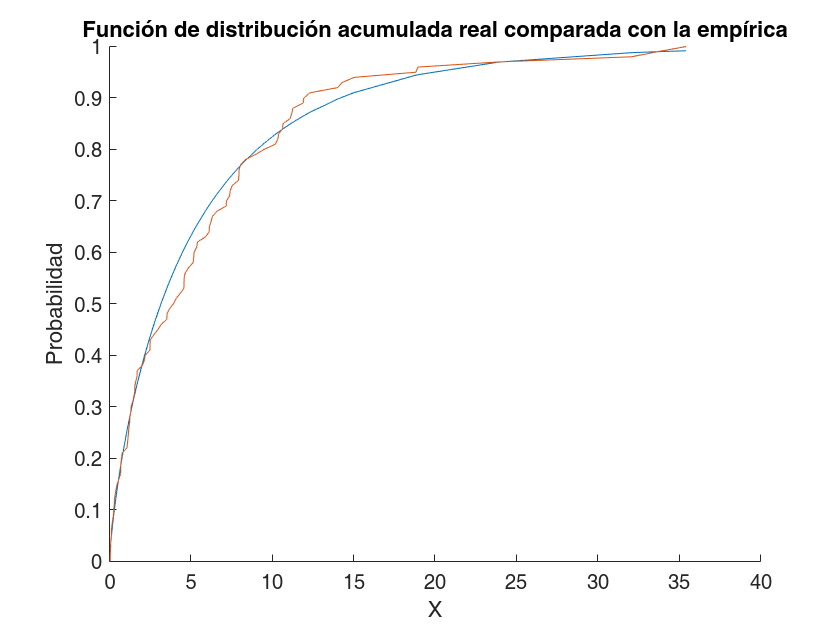

clf
hold on
plot(t,WeibulF)
plot(t,F)
title("Función de distribución acumulada real comparada con la empírica")
xlabel("X")
ylabel("Probabilidad")

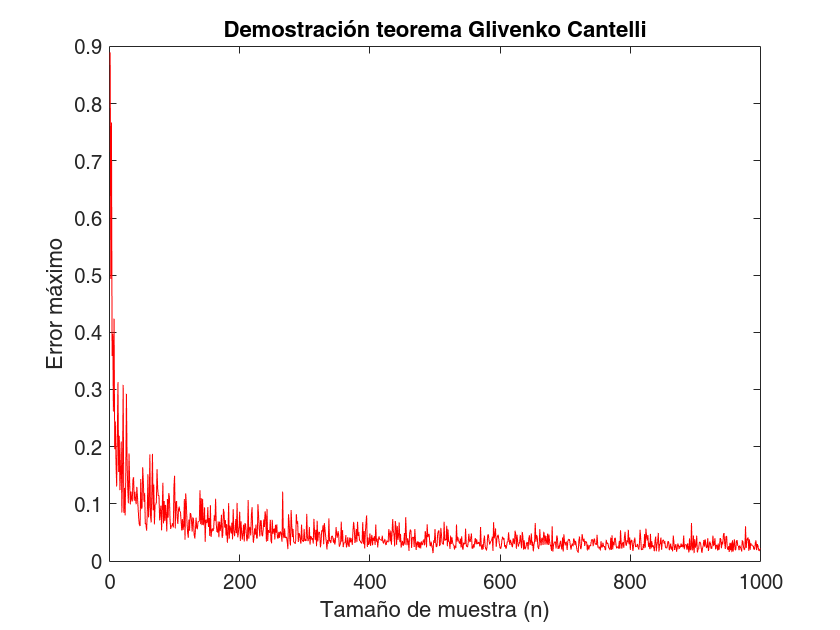

maxs = zeros(991,1);
for i = 1:1000
    X = wblrnd(5, 0.8,i,1);
    [F,t] = ecdf(X);
    WeibulF = wblcdf(t,5,0.8);
    maxs(i) = max(abs(WeibulF-F));
end
clf
plot(maxs,'r')
title("Demostración teorema Glivenko Cantelli")
xlabel("Tamaño de muestra (n)")
ylabel("Error máximo")

Punto 7

clf; clear all
syms i;
n=1000; N = 1000;
j = 5;

weibul = wblrnd(1,1,N,n);
weibulSort = sort(weibul);
ithValue = weibulSort(j,:);
[F,t] = ecdf(ithValue);

x = zeros(length(t),1);
for k=1:length(t)
    x(k) = double(symsum(nchoosek(n,i)*(wblcdf(t(k))^(i)*(1-wblcdf(t(k)))^(n-i)),i,j,n));
end

clf
plot(t,x,'r')
hold on
plot(t,F,'b')
legend({"Theoretical", "Empirical"})
xlabel('x'); ylabel('CDF(x)'); title("Comparison between a theorical and empirical CDF")

Punto 12

clf
[minimum, minindex] = min(means); minYear = Temps(:,minindex);
maxTemp = max(minYear)

maxTemp = 5

m = bootstrp(1000,@max,minYear);
mean(m)

ans = 4.9306

hist(m) %esperamos que se vea normal

%Varianza
var(m)

ans = 0.0145

%Intervalo de confianza
CIB = [prctile(m,2.5) prctile(m,97.5)] %Intervalo de confianza con bootstrap

CIB =     4.6000    5.0000


%Sesgo
jack = jackknife(@max,minYear);
n = length(minYear);

jbias = (n-1)*(mean(jack)-max(minYear))

jbias = -0.0997

Punto 13

clf
N = 1000;
n = 10;
unif = rand(N,n);
mins = min(unif(:,:));
m = bootstrp(100,@min,mins);
var(mins)

ans = 5.9454e-07

hist(m)

mean(mins) %Sample mean value

ans = 0.0010

-1/(N+1) %Expected mean value

ans = -9.9900e-04

%Sesgo Varianza
m1 = jackknife(@min,mins);
bias = 1/(N+1) %Known minimum bias estimate

bias = 9.9900e-04

jbias = (n-1)*(mean(m1)-min(mins)) %jackknife bias estimate

jbias = 1.7626e-04

Punto 14

%Bootstrap Parametrico
n =100;
B = 10000;
samples = zeros(B,1);
for i=1:B
    samp = normrnd(15,2,[n 1]);
    samples(i) = mean(samp);
end
LI = prctile(samples,2.5);
LS = prctile(samples,97.5);
ci_p = [LI LS]

ci_p =    14.6050   15.4002


variance = var(samples)

variance = 0.0407

%Non parametic Bootstrap
n = 100;
B = 10000;
samples2 = normrnd(15,1,[n 1]);
[ci_np, ~] = bootci(B, @mean, samples2)

ci_np =    14.6945
   15.5158


%Bootstrap Robusto
B = 10000;
n_cont = 11;
n = 100;

muestras = normrnd(15,1,[n 1]) + 0.5*rand([n 1]);
[ci_nr,~] = bootci(B,@mean,muestras)

ci_nr =    15.0716
   15.4821


[winsorized,~]=winsor(muestras,[2.5;97.5]);
min(winsorized), max(winsorized)

ans = 13.5352

ans = 17.4341

Punto 15

clf
[minimum, minindex] = min(means); minYear = Temps(:,minindex);
[maximum, maxindex] = max(means); maxYear = Temps(:,maxindex);
clf
dist = mahal(maxYear,minYear);
p = prctile(dist,95);
idx = find(dist>p);
plot(minYear, maxYear, '.')
hold on
plot(Temps(idx,minindex), Temps(idx,maxindex), '+')
title("Detección de outliers Mahalanobis clásica")
xlabel("Temperaturas más calurosas en media")
ylabel("Temperatura más frías en media")
legend('','Outliers')

clf
X = minYear; Y =maxYear; m = mean(X,1); m2 = mean(Y,1)

m2 = 9.9592

[rx,cx] = size(X); [ry,cy] = size(Y);
M = m(ones(ry,1),:);
C = X - m(ones(rx,1),:); 
covarian = corr([X,Y])*std(X)*std(Y);
x_minus_mu = [Y,X]-[maximum minimum];
left_term = x_minus_mu/covarian;
mahal_nueva = sqrt(left_term* x_minus_mu');
dist = diag(mahal_nueva);
p = prctile(dist,95);
idx = find(dist>p);
plot(minYear, maxYear, '.')
hold on
plot(Temps(idx,mint), Temps(idx,maxt), '+')
title("Detección de outliers Mahalanobis clásica")
xlabel("Temperaturas más calurosas en media")
ylabel("Temperatura más frías en media")
legend('','Outliers')

Punto 16.1

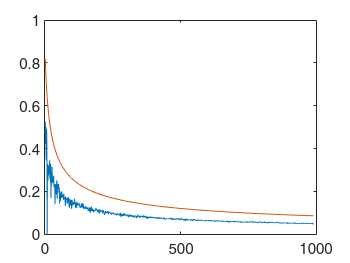

clf
N=1000;
sizenorm = zeros(n,1); sizenopar = zeros(n,1);
for n=11:N
    X = binornd(1,0.2, n,1);
    pn = 1/n*sum(X);
    CInorm = [pn + norminv(0.025)*sqrt(pn*(1-pn)/n);
              pn + norminv(0.975)*sqrt(pn*(1-pn)/n)];
    sizenorm(n-10) = CInorm(2)-CInorm(1);
    CInopar =  [pn - sqrt(1/(2*n)*log(2/0.05));
                 pn + sqrt(1/(2*n)*log(2/0.05))];
    sizenopar(n-10) = CInopar(2)-CInopar(1);
end
plot(sizenorm)
hold on 
plot(sizenopar)

punto 16.2

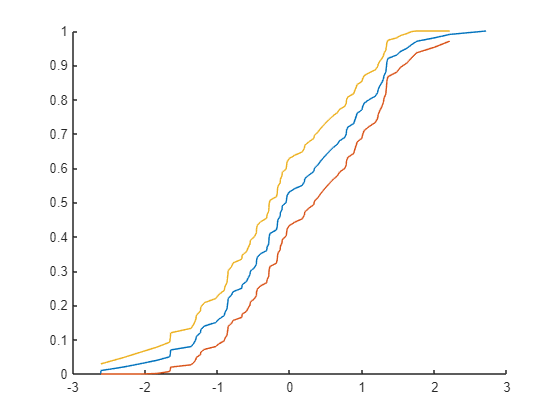

clf
N = 100;
X = randn(N,1);
[Fout,x,Flo,Fup] = ecdf(X,"Bounds","on");
hold on
plot(x,Fout), plot(x,Flo), plot(x,Fup)

N = 100;
alpha = 0.05;
sumsMat = 0;
sumsWasser = 0;
epsilon= sqrt(1/(2*N)*log(2/alpha));
for i=1:1000
    X = randn(N,1);
    [F,x,Flo,Fup] = ecdf(X,"Bounds","on");
    Up=zeros(length(F),1); Lo=zeros(length(F),1);
    normal = normcdf(x,0,1);
    for j= 1:length(F)
    Up(j)= min(F(j)+epsilon,1);
    Lo(j) = max(F(j)-epsilon,0);
    end
    if sum(normal>Fup) + sum(normal<Flo)>=1 
        sumsMat = sumsMat+1;
    end
    if sum(normal>Up) + sum(normal<Lo)>=1 
        sumsWasser = sumsWasser+1;
    end
end
1 - sumsMat/1000

ans = 0.4020

1- sumsWasser/1000

ans = 0.9560

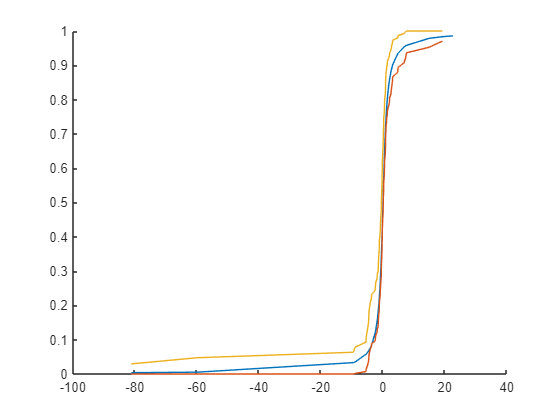

%Cauchy Distribution
clf
N = 100;
X = trnd(1,N,1);
outBounds = 0;
[Fout,x,Flo,Fup,D] = ecdf(X,"Bounds","on");
hold on
plot(x,tcdf(x,1)), plot(x,Flo), plot(x,Fup)

N = 100;
alpha = 0.05;
sumsMat = 0;
sumsWasser = 0;
epsilon= sqrt(1/(2*N)*log(2/alpha));
for i=1:1000
    X = trnd(1,[N 1]);
    [F,x,Flo,Fup] = ecdf(X,"Bounds","on");
    Up=zeros(length(F),1); Lo=zeros(length(F),1);
    normal = tcdf(x,1);
    for j= 1:length(F)
    Up(j)= min(F(j)+epsilon,1);
    Lo(j) = max(F(j)-epsilon,0);
    end
    if sum(normal>Fup) + sum(normal<Flo)>=1 
        sumsMat = sumsMat+1;
    end
    if sum(normal>Up) + sum(normal<Lo)>=1 
        sumsWasser = sumsWasser+1;
    end
end
1 - sumsMat/1000

ans = 0.4190

1- sumsWasser/1000

ans = 0.9660

punto 16.4

%%
%Exercise 16.4
clf
LSAT = [576 635 558 578 666 580 555 661 651 605 653 575 545 572 594]';
GPA = [3.39 3.3 2.81 3.03 3.44 3.07 3 3.43 3.36 3.13 3.12 2.74 2.76 2.88 3.96]';
n = length(LSAT)

n = 15

X = [LSAT GPA];

plot(GPA,LSAT,'o','color','#D95319')
title('Correlation')
xlabel('GPA')
ylabel('LSAT')

% correlation coefficient
GPAbar = mean(GPA); LSATbar =  mean(LSAT);
p = sum((GPA-GPAbar).*(LSAT -LSATbar))/(sqrt(sum((GPA-GPAbar).^2)).*sqrt(sum((LSAT-LSATbar).^2)))

p = 0.5459

p = corr(GPA,LSAT)

p = 0.5459


%Standard error using influence function
sqrt((LSAT'*GPA - (GPA'*GPA+LSAT'*LSAT)*p/2)/n)

ans = 0.0000e+00 + 3.1128e+02i


%Standard error using jackknife


%Standard error using bootstrap
boot = bootstrp(1000,@corr,X);
BootstrapExpected = mean(boot);
BootstrapExpected = BootstrapExpected(2)

BootstrapExpected = 0.5682

std(boot)/sqrt(n)

ans =          0    0.0504    0.0504         0


m = 100;
boots = zeros(m,1);
for i = 1:m
    boot = bootstrp(1000,@corr,X);
    BootstrapExpected = mean(boot);
    boots(i) = BootstrapExpected(2);
end

std(boots)

punto 16.6